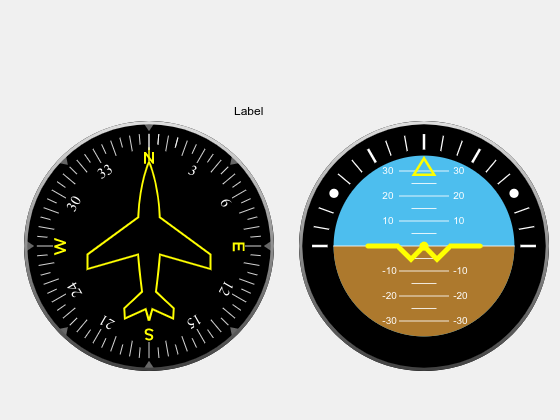

% MATLAB Script: read_quat.m
% This script listens on a serial port and extracts t, qw, qx, qy, and qz from lines
% that match the pattern:
% I (10843) LOGGER_TASK: Current Quat at time 10.1784: 0.9999, -0.0023, -0.0044, -0.0147

% Specify the serial port and baud rate (adjust as needed)
port = '/dev/ttyUSB0';       % Replace with your serial port (e.g., '/dev/ttyUSB0' on Linux)
baudRate = 921600;   % Adjust baud rate if required

% Open the serial port (using the serialport object available in recent MATLAB versions)
if (~exist("s", "var"))
    s = serialport(port, baudRate);
end
f = uifigure;
heading = uiaeroheading(f);
horizon = uiaerohorizon(f);
txt = uilabel(f);
heading.Position = [25 50 250 250];
horizon.Position = [300 50 250 250];
txt.Position = [235 300 100 20];

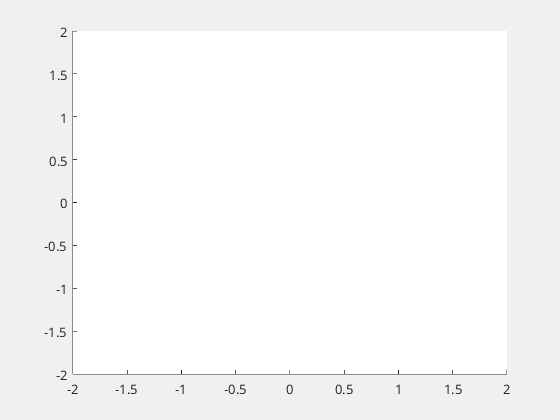


fig = figure("Visible","on");
ax = axes(fig);
ax.XLimMode = "manual";
ax.YLimMode = "manual";
ax.ZLimMode = "manual";

stlFile = 'body.stl'; % Change this to your STL file name
fv = stlread(stlFile); % Read STL file
ax.XLim = [-1,1]*2;
ax.YLim = [-1,1]*2;
ax.ZLim = [-1,1]*2;




q = quaternion(1,0,0,0);

% Optionally, flush any old data from the serial port
flush(s);

disp('Listening for quaternion messages...');

Listening for quaternion messages...



% Define the regular expression pattern for extracting the desired values:
% - It looks for "Current Quat at time" followed by a time value,
%   then a colon, then four comma-separated numbers.
patternQ = 'Current Quat at time ([0-9]+\.[0-9]+):\s*([-+]?[0-9]*\.?[0-9]+),\s*([-+]?[0-9]*\.?[0-9]+),\s*([-+]?[0-9]*\.?[0-9]+),\s*([-+]?[0-9]*\.?[0-9]+)';
patternM = "Magnetometer values: X: (-?\d+\.\d{2}), Y: (-?\d+\.\d{2}), Z: (-?\d+\.\d{2})";


eul = [0 0 0];
qw = 1;
qx=0;
qy=0;
qz=0;
% Start an infinite loop to continuously read from the serial port.

while true
    % Read one line from the serial port

    tokensQ = {};
    tokensM = {};


    while isempty(tokensQ)
        line = readline(s);
        tokensQ = regexp(line, patternQ, 'tokens');
    end
    % Extract tokens from the first match
    token = tokensQ{1};
    tokensQ = {};
    t  = sscanf(token{1},"%f");
    qw = str2double(token{2});
    qx = str2double(token{3});
    qy = str2double(token{4});
    qz = str2double(token{5});

    q2 = [qw,qx,qy,qz];
    eul = quaternion(q2);
    eul = eul.euler("ZYX", "frame");



    while isempty(tokensM)
        line = readline(s);
        % Extract tokens from the first match
        tokensM = regexp(line, patternM, 'tokens');


    end


    token = tokensM{1};
    tokenM = {};
    mx = str2double(token{1});
    my = str2double(token{2});
    mz = str2double(token{3});

    mNorm = sqrt([mx my mz]*[mx my mz]');
    mx = mx/mNorm;
    my = my/mNorm;
    mz = mz/mNorm;

    R = so3([0 eul(2) eul(3)], "eul","ZYX").rotm;

    mC = [mx,my,mz]*R;
    h.XData(2) = mC(1);
    h.YData(2) = mC(2);
    h.ZData(2) = mC(3);
    magHeading = atan2(mC(2),mC(1));
    imuHeading = eul(1);
    diffHead = magHeading-imuHeading;

    q1 = [cos(diffHead/2),0,0,sin(diffHead/2)];


    R = so3(q2, "quat","ZYX").rotm;
    txt.Text = string(t);
    heading.Value = rad2deg(magHeading);
    horizon.Value =  rad2deg(fliplr(eul(2:3)));
    fvR =  triangulation(fv.ConnectivityList,(R * fv.Points')');
    trisurf(fvR, 'FaceColor', [0.8 0.8 1.0]); % Light blue model
    ax.XLim = [-1,1]*2;
    ax.YLim = [-1,1]*2;
    ax.ZLim = [-1,1]*2;

    %fprintf('mx: %f, my: %f, mz: %f\n', mC(1),mC(2),mC(3));
    % Display or process the extracted values
    %fprintf('t: %f, qw: %f, qx: %f, qy: %f, qz: %f\n', t, qw, qx, qy, qz);




    % Optionally, add a pause to avoid busy-waiting
    pause(0.1);
end